folder = 'D:\Matlab\bin\UCLA\TorORd_frat_RR_seq';
files = dir(fullfile(folder, '*.dat'));
k=58;
filename = fullfile(folder, files(k).name);
files(k).name

ans = 'RR_real_0009.dat'

rr = load(filename);
%rr(1001:2000)=[];
rr=rr-mean(rr);
Y=fft(rr);
P = abs(Y).^2;
P=P/(998*2000);

[PSD,f] = pwelch(rr);

rrs = rr(randperm(length(rr)));
%rrs=rrs-mean(rrs);
Y2=fft(rrs);
P2 = abs(Y2).^2;
P2=P2/(998*2000);

[PSD2,f2] = pwelch(rrs);

k2=108;
filename2 = fullfile(folder, files(k2).name);
files(k2).name

ans = 'RR_simu_0009.dat'

rr3 = load(filename2);
%rr(1001:2000)=[];
rr3=rr3-mean(rr3);
Y3=fft(rr3);
P3 = abs(Y3).^2;
P3=P3/(998*2000);

[PSD3,f3] = pwelch(rr3);

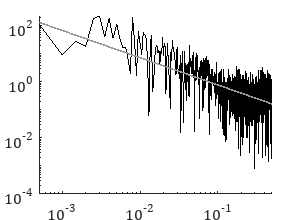

Ph=P(1:0.5*length(P));
ff=linspace(0,0.5,length(Ph));
figure
loglog(ff,Ph,'k')
hold on
logf   = log10(ff(2:length(ff)));
logPSD = log10(Ph(2:length(Ph)));
pf = polyfit(logf, logPSD, 1);

PSD_fit = 10.^(polyval(pf,logf));

loglog(ff(2:length(ff)),PSD_fit,'color','[0.6 0.6 0.6]','LineWidth',1.2)

xlim([min(ff) max(ff)])
xticks([10^(-3) 10^(-2) 10^(-1)])
%yticks([10^(3) 10^(6) 10^(9)])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

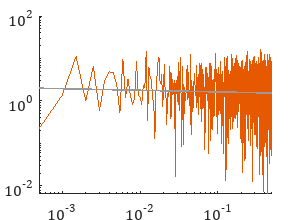



Ph2=P2(1:0.5*length(P2));
ff2=linspace(0,0.5,length(Ph2));
figure
%subplot(2,1,1)
loglog(ff2,Ph2,'color','[0.90 0.35 0]')

hold on
logf2   = log10(ff2(2:length(ff2)));
logPSD2 = log10(Ph2(2:length(Ph2)));
pf2 = polyfit(logf2, logPSD2, 1);

PSD_fit2 = 10.^(polyval(pf2,logf2));

loglog(ff2(2:length(ff2)),PSD_fit2,'color','[0.6 0.6 0.6]','LineWidth',1.2)

xlim([min(ff2) max(ff2)])
xticks([10^(-3) 10^(-2) 10^(-1)])
%yticks([10^(4) 10^(6) 10^(8)])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

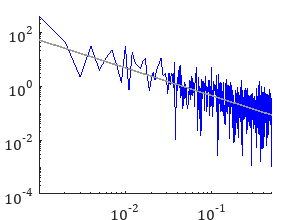



Ph3=P3(1:0.5*length(P3));
ff3=linspace(0,0.5,length(Ph3));
figure
%subplot(2,1,2)
loglog(ff3,Ph3,'b')

hold on
logf3   = log10(ff3(2:length(ff3)));
logPSD3 = log10(Ph3(2:length(Ph3)));
pf3 = polyfit(logf3, logPSD3, 1);

PSD_fit3 = 10.^(polyval(pf3,logf3));

loglog(ff3(2:length(ff3)),PSD_fit3,'color','[0.6 0.6 0.6]','LineWidth',1.2)

xlim([min(ff3) max(ff3)])
xticks([10^(-3) 10^(-2) 10^(-1)])
yticks([10^(-4) 10^(-2) 10^(0) 10^(2)])
%yticks([10^(4) 10^(6) 10^(8)])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

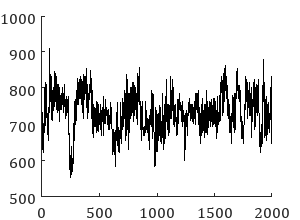

rry = load(filename);

figure
plot(rr+mean(rry(1:1000)),'k')
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

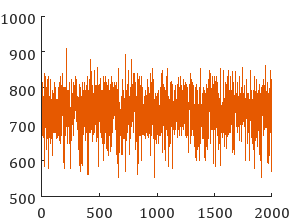


figure
plot(rrs+mean(rry(1:1000)),'Color','[0.90 0.35 0]')
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

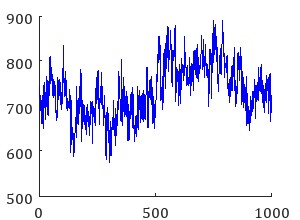


figure
plot(rr3+mean(rry(1:1000)),'b')
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

QT_gaus=QTn(:,1:50);QT_real=QTn(:,51:100);
QT_simu=QTn(:,101:150);QT_surr=QTn(:,151:200);

ii=1:1:37;ii([3,35])=[];%ii(1:1:11)=[];
%ii=38:1:49;
QTm_ni_ga=mean(std(QT_gaus(:,ii)))

QTm_ni_ga = 3.5851

QTm_ni_re=mean(std(QT_real(:,ii)))

QTm_ni_re = 4.9811

QTm_ni_si=mean(std(QT_simu(:,ii)))

QTm_ni_si = 4.8629

QTm_ni_su=mean(std(QT_surr(:,ii)))

QTm_ni_su = 4.8370

QTm_ni_sh=QTm_ni_ga+0.04*rand

QTm_ni_sh = 3.5881

QTm_ni_sa=QTm_ni_ga+0.04*rand

QTm_ni_sa = 3.5872


QTVim_ni_ga=mean(QTVi_gaus(ii))

函数或变量 'QTVi_gaus' 无法识别。

QTVim_ni_re=mean(QTVi_real(ii))
QTVim_ni_si=mean(QTVi_simu(ii))
QTVim_ni_su=mean(QTVi_surr(ii))
QTVim_ni_sh=QTVim_ni_ga+0.02*rand
QTVim_ni_sa=QTVim_ni_ga+0.02*rand

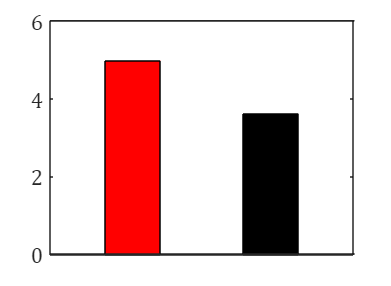

figure
bar(1,QTm_ni_re,'FaceColor', 'r')
hold on
bar(3,QTm_ni_sh,'FaceColor', 'k')
xticks([])
ylim([0 6])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

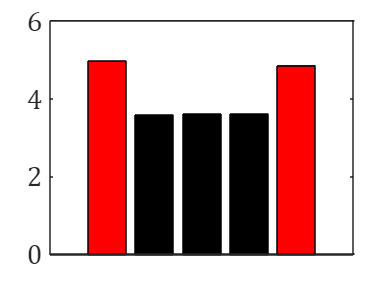

figure
bar(1,QTm_ni_re,'FaceColor', 'r')
hold on
bar(2,QTm_ni_ga,'FaceColor', 'k')
bar(3,QTm_ni_sh,'FaceColor', 'k')
bar(4,QTm_ni_sa,'FaceColor', 'k')
bar(5,QTm_ni_si,'FaceColor', 'r')
xticks([])
ylim([0 6])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',15)
set (gcf,'Position',[500,100,300,220])

figure
bar(1,QTVim_ni_re,'FaceColor', 'r')
hold on
bar(2,QTVim_ni_ga,'FaceColor', 'k')
bar(3,QTVim_ni_sh,'FaceColor', 'k')
bar(4,QTVim_ni_sa,'FaceColor', 'k')
bar(5,QTVim_ni_si,'FaceColor', 'r')
xticks([])
ylim([-2.2 0])
yticks([-2 -1 0])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',15)
set (gcf,'Position',[500,100,300,220])

N_sub=37;
ii=1:1:N_sub;ii([3,12,26,32,35])=[];
ii2=[1,4,5,8,9,13,20,29];


QTVm_l_ga1=mean(std(QT_gaus_l1(:,ii)))

QTVm_l_ga1 = 3.2203

QTVm_l_ga2=mean(std(QT_gaus_l2(:,ii)))

QTVm_l_ga2 = 7.1286

QTVm_l_ga3=mean(std(QT_gaus_l3(:,ii)))

QTVm_l_ga3 = 23.5062



QTVm_l_re1=mean(std(QT_real_l1(:,ii)))

QTVm_l_re1 = 4.5945

QTVm_l_re2=mean(std(QT_real_l2(:,ii)))

QTVm_l_re2 = 8.0973

QTVm_l_re3=mean(std(QT_real_l3(:,ii)))

QTVm_l_re3 = 20.4292


QTVm_l_si1=mean(std(QT_simu_l1(:,ii)))

QTVm_l_si1 = 4.4279

QTVm_l_si2=mean(std(QT_simu_l2(:,ii)))

QTVm_l_si2 = 8.0206

QTVm_l_si3=mean(std(QT_simu_l3(:,ii)))

QTVm_l_si3 = 20.3776


QTVm_l_su1=mean(std(QT_surr_l1(:,ii)))

QTVm_l_su1 = 4.4326

QTVm_l_su2=mean(std(QT_surr_l2(:,ii)))

QTVm_l_su2 = 7.8830

QTVm_l_su3=mean(std(QT_surr_l3(:,ii)))

QTVm_l_su3 = 19.9833


QTVm_l_sh1=QTVm_l_ga1+0.3*rand

QTVm_l_sh1 = 3.4170

QTVm_l_sa1=QTVm_l_ga1+0.3*rand

QTVm_l_sa1 = 3.2310


QTVm_l_sh2=QTVm_l_ga2+0.3*rand

QTVm_l_sh2 = 7.3833

QTVm_l_sa2=QTVm_l_ga2+0.3*rand

QTVm_l_sa2 = 7.4088


QTVm_l_sh3=QTVm_l_ga3+0.3*rand

QTVm_l_sh3 = 23.7099

QTVm_l_sa3=QTVm_l_ga3+0.3*rand

QTVm_l_sa3 = 23.7336

figure
bar(1,QTVm_l_re3,'FaceColor', 'r')
hold on
bar(2,QTVm_l_ga3,'FaceColor', 'k')
bar(3,QTVm_l_sh3,'FaceColor', 'k')
bar(4,QTVm_l_sa3,'FaceColor', 'k')
bar(5,QTVm_l_si3,'FaceColor', 'r')
xticks([])
ylim([0 30])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',15)
set (gcf,'Position',[500,100,300,220])

ii1=1:1:50;ii1([3,32,35,39,47])=[];
RR_real=RRn(:,51:100);
RRm_re=mean(RR_real(:,ii1));
ii2=find(RRm_re>450)

ii2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    36    42


ii3=find(RRm_re<450)

ii3 =     35    37    38    39    40    41    43    44    45



QTVm_l_re0=mean(std(QT_real(:,ii1(ii2))))

QTVm_l_re0 = 4.7504

QTVm_l_si0=mean(std(QT_simu(:,ii1(ii2))))

QTVm_l_si0 = 4.6891

QTVm_l_ga0=mean(std(QT_gaus(:,ii1(ii2))))

QTVm_l_ga0 = 3.3877

QTVm_l_su0=mean(std(QT_surr(:,ii1(ii2))))

QTVm_l_su0 = 4.6228


QTVm_s_re0=mean(std(QT_real(:,ii1(ii3))))

QTVm_s_re0 = 3.1569

QTVm_s_si0=mean(std(QT_simu(:,ii1(ii3))))

QTVm_s_si0 = 3.5655

QTVm_s_ga0=mean(std(QT_gaus(:,ii1(ii3))))

QTVm_s_ga0 = 4.0727

QTVm_s_su0=mean(std(QT_surr(:,ii1(ii3))))

QTVm_s_su0 = 3.1835


em_s_re0=std(std(QT_real(:,ii1(ii3))))

em_s_re0 = 0.7831

em_s_ga0=std(std(QT_gaus(:,ii1(ii3))))

em_s_ga0 = 1.3149

em_s_sh0=std(std(QT_gaus(:,ii1(ii3))))+0.3*rand

em_s_sh0 = 1.5277

em_s_si0=std(std(QT_simu(:,ii1(ii3))))

em_s_si0 = 1.1661


em_l_re0=std(std(QT_real(:,ii1(ii2))))

em_l_re0 = 1.6674

em_l_ga0=std(std(QT_gaus(:,ii1(ii2))))

em_l_ga0 = 1.0977

em_l_sh0=std(std(QT_gaus(:,ii1(ii2))))+0.3*rand

em_l_sh0 = 1.3241

em_l_si0=std(std(QT_simu(:,ii1(ii2))))

em_l_si0 = 1.4139


em_l_re2=std(std(QT_real_l2(:,ii)))

em_l_re2 = 2.3428

em_l_ga2=std(std(QT_gaus_l2(:,ii)))

em_l_ga2 = 2.8611

em_l_sh2=std(std(QT_gaus_l2(:,ii)))+0.3*rand

em_l_sh2 = 2.9439

em_l_si2=std(std(QT_simu_l2(:,ii)))

em_l_si2 = 1.9246


em_l_re3=std(std(QT_real_l3(:,ii)))

em_l_re3 = 4.9467

em_l_ga3=std(std(QT_gaus_l3(:,ii)))

em_l_ga3 = 7.0705

em_l_sh3=std(std(QT_gaus_l3(:,ii)))+0.3*rand

em_l_sh3 = 7.2744

em_l_si3=std(std(QT_simu_l3(:,ii)))

em_l_si3 = 4.6164

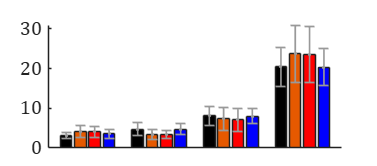

figure
n=0;
bar(1+n,QTVm_s_re0,'FaceColor', 'k')
hold on
bar(3+n,QTVm_s_ga0,'FaceColor', 'r')
bar(2+n,QTVm_s_ga0+0.1*rand,'FaceColor', '[0.90 0.35 0]')
bar(4+n,QTVm_s_si0,'FaceColor', 'b')

n=5;
bar(1+n,QTVm_l_re0,'FaceColor', 'k')
bar(3+n,QTVm_l_ga0,'FaceColor', 'r')
bar(2+n,QTVm_l_ga0+0.1*rand,'FaceColor', '[0.90 0.35 0]')
bar(4+n,QTVm_l_si0,'FaceColor', 'b')

%n=6;
%bar(1+n,QTVm_l_re1,'FaceColor', 'k')
%bar(2+n,QTVm_l_si1,'FaceColor', 'r')

n=10;
bar(1+n,QTVm_l_re2,'FaceColor', 'k')
bar(3+n,QTVm_l_ga2,'FaceColor', 'r')
bar(2+n,QTVm_l_sh2,'FaceColor', '[0.90 0.35 0]')
bar(4+n,QTVm_l_si2,'FaceColor', 'b')

n=15;
%bar(1+n,mean(QTg3v_re),'FaceColor', 'k')
%bar(2+n,mean(QTg3v_ga),'FaceColor', 'r')
%bar(3+n,mean(QTg3v_sh)+0.6,'FaceColor', '[0.65 0 0]')
%bar(4+n,mean(QTg3v_si),'FaceColor', 'b')
bar(1+n,QTVm_l_re3,'FaceColor', 'k')
bar(3+n,QTVm_l_ga3,'FaceColor', 'r')
bar(2+n,QTVm_l_sh3,'FaceColor', '[0.90 0.35 0]')
bar(4+n,QTVm_l_si3,'FaceColor', 'b')

xx=[1,2,3,4,6,7,8,9,11,12,13,14,16,17,18,19];
yy(1:8)=[QTVm_s_re0,QTVm_s_ga0+0.1*rand,QTVm_s_ga0,QTVm_s_si0,QTVm_l_re0,QTVm_l_ga0+0.1*rand,QTVm_l_ga0,QTVm_l_si0];
yy(9:16)=[QTVm_l_re2,QTVm_l_sh2,QTVm_l_ga2,QTVm_l_si2,QTVm_l_re3,QTVm_l_sh3,QTVm_l_ga3,QTVm_l_si3];
ee(1:8)=[em_s_re0,em_s_sh0,em_s_ga0,em_s_si0,em_l_re0,em_l_sh0,em_l_ga0,em_l_si0];
ee(9:16)=[em_l_re2,em_l_sh2,em_l_ga2,em_l_si2,em_l_re3,em_l_sh3,em_l_ga3,em_l_si3];
errorbar(xx,yy,ee,'.','color','[0.6 0.6 0.6]','LineWidth',1)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,500,220])
xticks([])

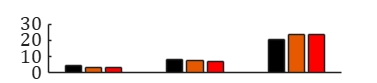

figure

%bar(1,QTm_ni_re,'FaceColor', 'r')
bar(1,QTVm_l_re1,'FaceColor', 'k')
hold on
bar(3,QTVm_l_ga1,'FaceColor', 'r')
bar(2,QTVm_l_sh1,'FaceColor', '[0.90 0.35 0]')
%bar(4,QTVm_l_sa1,'FaceColor', 'r')
%bar(5,QTVm_l_re1,'FaceColor', 'r')

n=5;
bar(1+n,QTVm_l_re2,'FaceColor', 'k')
hold on
bar(3+n,QTVm_l_ga2,'FaceColor', 'r')
bar(2+n,QTVm_l_sh2,'FaceColor', '[0.90 0.35 0]')
%bar(4+n,QTVm_l_sa2,'FaceColor', 'r')
%bar(5+n,QTVm_l_si2,'FaceColor', 'r')

n=10;
bar(1+n,QTVm_l_re3,'FaceColor', 'k')
hold on
bar(3+n,QTVm_l_ga3,'FaceColor', 'r')
bar(2+n,QTVm_l_sh3,'FaceColor', '[0.90 0.35 0]')
%bar(4+n,QTVm_l_sa3,'FaceColor', 'r')
%bar(5+n,QTVm_l_si3,'FaceColor', 'r')
xticks([])
ylim([0 30])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

set (gcf,'Position',[500,100,1000,220])

vv0=load("Tissue_1000_0.dat");
vv1=load("Tissue_1000_1.dat");
vv2=load("Tissue_1000_2.dat");
vv3=load("Tissue_1000_3.dat");
vv3=load("Tissue_GKr03_1000_2.dat");

figure
%plot(vv1(500:2000,1),vv1(500:2000,2))
%hold on
%plot(vv0(500:2000,1),vv0(500:2000,2))
plot(vv1(500:2000,2))
hold on
plot(vv0(1:2000,2))

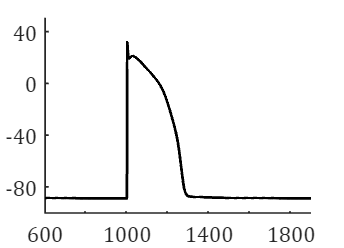

figure
xx=linspace(600,1900,1300);
plot(xx,vv1(601:1900,2),'k','LineWidth',1.5)
hold on
xx=linspace(600,1900,13000);
%plot(xx,vv0(6001:19000,2),'--k','LineWidth',1.5)
set (gcf,'Position',[500,100,250,180])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([600 1900])
ylim([-100 50])
yticks([-80 -40 0 40])

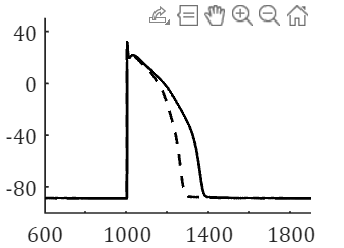

figure
xx=linspace(600,1900,1300);
plot(xx,vv2(601:1900,2),'k','LineWidth',1.5)
hold on
xx=linspace(600,1900,13000);
plot(xx,vv0(6001:19000,2),'--k','LineWidth',1.5)
set (gcf,'Position',[500,100,250,180])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([600 1900])
ylim([-100 50])
yticks([-80 -40 0 40])

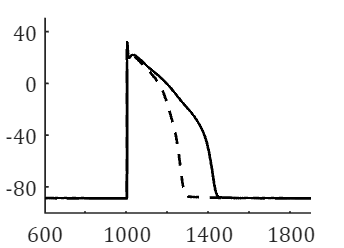

figure
xx=linspace(600,1900,1300);
plot(xx,vv3(601:1900,2),'k','LineWidth',1.5)
hold on
xx=linspace(600,1900,13000);
plot(xx,vv0(6001:19000,2),'--k','LineWidth',1.5)
set (gcf,'Position',[500,100,250,180])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([600 1900])
ylim([-100 50])
yticks([-80 -40 0 40])

clear Gain_r
clear QTV_est_r1
clear QTV_real1
nn=91;
for nn=1:148
    nn2=iii(nn);
rr=RRn(:,nn2);%dd=DIn(:,nn2);
N = length(RRn(:,nn2));
Kmax=49;Kmax_di=0;
if Kmax_di==0
    XX = zeros(N-Kmax-2, Kmax+1);
else
    XX = zeros(N-Kmax, Kmax+Kmax_di+2);
end
Y = QTn(Kmax+2:N-1,nn2);
YY=Y-mean(Y);

rr2=rr-mean(rr);
for k = 0:Kmax
    XX(:, k+1) = rr2(Kmax+1-k:N-k-2);
end

%X(:,Kmax+2)=1;

if Kmax_di>0
    if Kmax_di<=Kmax
        for k =0:Kmax_di
            XX(:,Kmax+2+k) = dd(Kmax+1-k:N-k);
        end
    end
end

% 最小二乘
K = XX \ YY;

K_r(:,nn)=K;

H=freqz(K,1,1024);
Gain=abs(H).^2;
rr0=rr-mean(rr);

[PSD,f]=pwelch(rr0,[],[],2046);

df=f(2)-f(1);

QTV_est_r1(nn)=(sum(Gain(1:length(PSD)).*PSD)*df)^0.5;
QTV_real1(nn)=std(Y);
PSD_r(nn,:)=PSD;

Gain_r(nn,:)=Gain;
%K_r1(nn,:)=K;

end

ss=1:1:37;
ss([3,12,26,32,35])=[];
ii(1:32)=ss;
ii(32+1:2*32)=ss+37;
ii(2*32+1:3*32)=ss+74;
ii(3*32+1:4*32)=ss+111;

ss=1:1:37;
iii(1:37)=ss;
iii(37+1:2*37)=ss+50;
iii(2*37+1:3*37)=ss+100;
iii(3*37+1:4*37)=ss+150;

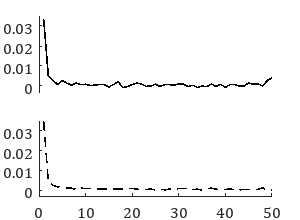

figure
subplot(2,1,1)
plot(K_r(:,58),'k','linewidth',1.2)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([0 50])
ylim([-0.003,0.035])
subplot(2,1,2)
plot(K_r(:,8),'--k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
%xlim([-0.02 0.5])
set (gcf,'Position',[500,100,300,220])
xlim([0 50])
ylim([-0.003,0.035])

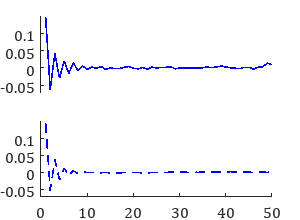

figure
subplot(2,1,1)
plot(K_r(:,91),'b','linewidth',1.2)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([0 50])
ylim([-0.07,0.15])
subplot(2,1,2)
plot(K_r(:,41),'--b','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
%xlim([-0.02 0.5])
set (gcf,'Position',[500,100,300,220])
xlim([0 50])
ylim([-0.07,0.15])

nn=91;
rr=RRn(:,nn);dd=DIn(:,nn);
N = length(RRn(:,nn));
Kmax=49;Kmax_di=0;
if Kmax_di==0
    XX = zeros(N-Kmax-2, Kmax+1);
else
    XX = zeros(N-Kmax, Kmax+Kmax_di+2);
end
Y = QTn(Kmax+2:N-1,nn);MY=mean(Y);
YY=Y-MY;

MR=mean(rr);
rr2=rr-MR;
for k = 0:Kmax
    XX(:, k+1) = rr2(Kmax+1-k:N-k-2);
end

%X(:,Kmax+2)=1;

if Kmax_di>0
    if Kmax_di<=Kmax
        for k =0:Kmax_di
            XX(:,Kmax+2+k) = dd(Kmax+1-k:N-k);
        end
    end
end

% 最小二乘
K = XX \ YY;

KK2=K;%KK(5:length(KK))=0;
QT_r=XX*KK2;
QT_t2=QT_r+MY;QT_r2=YY+MY;

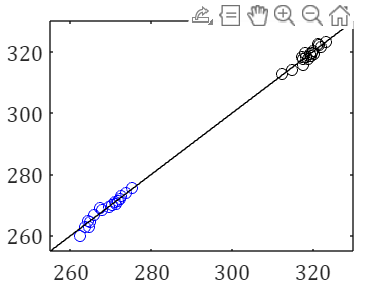

figure
plot(QT_t1(50:50:900),QT_r1(50:50:900),'ok')
hold on
plot(QT_t2(50:50:900),QT_r2(50:50:900),'ob')
xx=250:1:330;
plot(xx,xx,'k')
%xlim([min(QT_r)-2,max(QT_r)+2])
xlim([255 330])
ylim([255 330])
%xlabel('QT_{n,reproduced}')
%ylabel('QT_n (ms)')
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

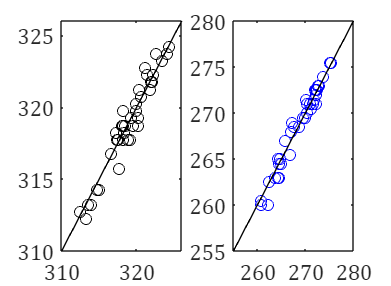

figure
subplot(1,2,1)
plot(QT_t1(25:25:925),QT_r1(25:25:925),'ok')
hold on
xx=250:1:330;
plot(xx,xx,'k')
%xlim([min(QT_r)-2,max(QT_r)+2])
xlim([310 326])
ylim([310 326])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

subplot(1,2,2)
plot(QT_t2(25:25:925),QT_r2(25:25:925),'ob')
hold on
xx=250:1:330;
plot(xx,xx,'k')
%xlim([min(QT_r)-2,max(QT_r)+2])
xlim([255 280])
ylim([255 280])
%xlabel('QT_{n,reproduced}')
%ylabel('QT_n (ms)')
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

ii1=1:1:50;ii1([3,32,35,39,47])=[];
RR_real=RRn(:,51:100);
RRm_re=mean(RR_real(:,ii1));
ii2=find(RRm_re>450)

ii2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    36    42


ii3=find(RRm_re<450)

ii3 =     35    37    38    39    40    41    43    44    45


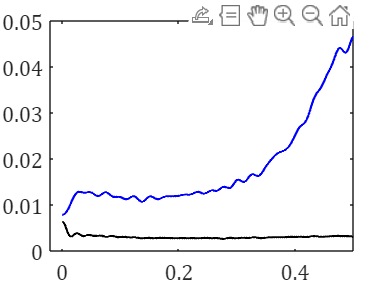

figure
xx=linspace(0,0.5,length(Gain));
plot(xx,mean(Gain_r1(ii1(ii2),:)),'k','linewidth',1.2)
hold on
plot(xx,mean(Gain_r1(ii1(ii3),:)),'b','linewidth',1.2)
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
set (gcf,'Position',[500,100,300,220])

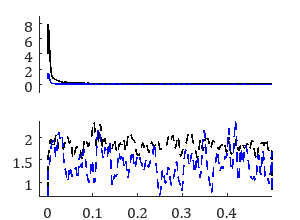

figure
subplot(2,1,1)
xx=linspace(0,0.5,length(PSD_r(1,:)));
plot(xx,0.0001*mean(PSD_r(ii1(ii2)+50,:)),'k','linewidth',1.2)
hold on
plot(xx,0.0001*mean(PSD_r(ii1(ii3)+50,:)),'b','linewidth',1.2)
%plot(xx,mean(PSD_r(ii1,:)),'r','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
%ylim([-9*10^3 9*10^4])
ylim([-1 9])
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(2,1,2)
plot(xx,0.001*mean(PSD_r(ii2,:)),'--k','linewidth',1.2)
hold on
plot(xx,0.001*mean(PSD_r(ii3,:)),'--b','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
set (gcf,'Position',[500,100,300,220])

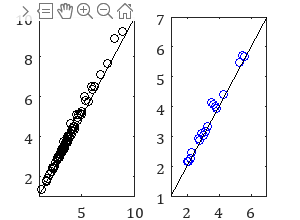

figure
subplot(1,2,1)
plot(QTV_est_r1(ii1(ii2)+50),QTV_real1(ii1(ii2)+50),'ok')
hold on
%plot(QTV_est_r1(ii1(ii3)+50),QTV_real1(ii1(ii3)+50),'ob')
plot(QTV_est_r1(ii1(ii2)),QTV_real1(ii1(ii2)),'ok')

xx=1:1:10;
plot(xx,xx,'k')
xlim([1 10])
ylim([1 10])
%plot(QTV_est_r3(ss),QTV_real3(ss),'.k')
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
%set (gcf,'Position',[500,100,300,220])
subplot(1,2,2)
%figure
plot(QTV_est_r1(ii1(ii3)+50),QTV_real1(ii1(ii3)+50),'ob')
hold on
%plot(QTV_est_r1(ii1(ii3)+50),QTV_real1(ii1(ii3)+50),'ob')
plot(QTV_est_r1(ii1(ii3)),QTV_real1(ii1(ii3)),'ob')

xx=1:1:10;
plot(xx,xx,'k')
xlim([1 7])
ylim([1 7])
%plot(QTV_est_r3(ss),QTV_real3(ss),'.k')
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

figure
xx=linspace(0,0.5,length(Gain));
plot(xx,mean(Gain_r1(ii,:)))

figure
plot(QTV_est_r(ii),QTV_real(ii),'.')

QTn1(:,1:37)=QT_gaus_l1(:,:);
QTn1(:,37+1:2*37)=QT_real_l1(:,:);
QTn1(:,2*37+1:3*37)=QT_simu_l1(:,:);
QTn1(:,3*37+1:4*37)=QT_surr_l1(:,:);

RRn1(:,1:37)=RR_gaus_l1(:,:);
RRn1(:,37+1:2*37)=RR_real_l1(:,:);
RRn1(:,2*37+1:3*37)=RR_simu_l1(:,:);
RRn1(:,3*37+1:4*37)=RR_surr_l1(:,:);

clear Gain_r1
clear QTV_est_r1
clear QTV_real1
nn=91;aa=1;
for nn=1:148
    nn2=nn;
rr=RRn1(:,nn2);%dd=DIn(:,nn2);
N = length(RRn1(:,nn2));
Kmax=49;Kmax_di=0;
if Kmax_di==0
    XX = zeros(N-Kmax-2, Kmax+1);
else
    XX = zeros(N-Kmax, Kmax+Kmax_di+2);
end
%QTn2=QT_gaus_l3(2:99,:);
Y = QTn1(Kmax+2:N-1,nn2);
YY=Y-mean(Y);

rr2=rr-mean(rr);
for k = 0:Kmax
    XX(:, k+1) = rr2(Kmax+1-k:N-k-2);
end

%X(:,Kmax+2)=1;

if Kmax_di>0
    if Kmax_di<=Kmax
        for k =0:Kmax_di
            XX(:,Kmax+2+k) = dd(Kmax+1-k:N-k);
        end
    end
end

% 最小二乘
K = XX \ YY;


H=freqz(K,1,1024);
Gain=abs(H).^2;
rr0=rr-mean(rr);

[PSD,f]=pwelch(rr0,[],[],2046);

df=f(2)-f(1);

QTV_est_r1(nn)=(sum(Gain(1:length(PSD)).*PSD)*df)^0.5;
QTV_real1(nn)=std(Y);

Gain_r1(nn,:)=Gain;
K_r1(nn,:)=K;
end

QTn3(:,1:37)=QT_gaus_l3(:,:);
QTn3(:,37+1:2*37)=QT_real_l3(:,:);
QTn3(:,2*37+1:3*37)=QT_simu_l3(:,:);
QTn3(:,3*37+1:4*37)=QT_surr_l3(:,:);

RRn3(:,1:37)=RR_gaus_l3(:,:);
RRn3(:,37+1:2*37)=RR_real_l3(:,:);
RRn3(:,2*37+1:3*37)=RR_simu_l3(:,:);
RRn3(:,3*37+1:4*37)=RR_surr_l3(:,:);

clear Gain_r3
clear QTV_est_r3
clear QTV_real3
nn=91;aa=1;
for nn=1:148
    nn2=nn;
rr=RRn3(:,nn2);%dd=DIn(:,nn2);
N = length(RRn3(:,nn2));
Kmax=49;Kmax_di=0;
if Kmax_di==0
    XX = zeros(N-Kmax-2, Kmax+1);
else
    XX = zeros(N-Kmax, Kmax+Kmax_di+2);
end
%QTn2=QT_gaus_l3(2:99,:);
Y = QTn3(Kmax+2:N-1,nn2);
YY=Y-mean(Y);

rr2=rr-mean(rr);
for k = 0:Kmax
    XX(:, k+1) = rr2(Kmax+1-k:N-k-2);
end

%X(:,Kmax+2)=1;

if Kmax_di>0
    if Kmax_di<=Kmax
        for k =0:Kmax_di
            XX(:,Kmax+2+k) = dd(Kmax+1-k:N-k);
        end
    end
end

% 最小二乘
K = XX \ YY;


H=freqz(K,1,1024);
Gain=abs(H).^2;
rr0=rr-mean(rr);

[PSD,f]=pwelch(rr0,[],[],2046);

df=f(2)-f(1);

QTV_est_r3(nn)=(sum(Gain(1:length(PSD)).*PSD)*df)^0.5;
QTV_real3(nn)=std(Y);

Gain_r3(nn,:)=Gain;
K_r3(nn,:)=K;
end

figure
xx=linspace(0,0.5,length(Gain));
plot(xx,mean(Gain_r3))

Gain_r2r(1:32,:)=Gain_r2(ii,:);
Gain_r2r(32+1:2*32,:)=Gain_r2(ii+37,:);
Gain_r2r(2*32+1:3*32,:)=Gain_r2(ii+2*37,:);
Gain_r2r(3*32+1:4*32,:)=Gain_r2(ii+3*37,:);

QTn2(:,1:37)=QT_gaus_l2(2:999,:);
QTn2(:,37+1:2*37)=QT_real_l2(2:999,:);
QTn2(:,2*37+1:3*37)=QT_simu_l2(2:999,:);
QTn2(:,3*37+1:4*37)=QT_surr_l2(2:999,:);

clear Gain_r2
clear QTV_est_r2
clear QTV_real2
nn=91;aa=1;
for nn=1:148
    nn2=(aa-1)*37+rem(nn,37);
    if nn2==0
        nn2=aa*37;
        aa=aa+1;
    end
rr=RRn(:,nn2);dd=DIn(:,nn2);
N = length(RRn(:,nn2));
Kmax=49;Kmax_di=0;
if Kmax_di==0
    XX = zeros(N-Kmax-2, Kmax+1);
else
    XX = zeros(N-Kmax, Kmax+Kmax_di+2);
end
%QTn2=QT_gaus_l3(2:99,:);
Y = QTn2(Kmax+2:N-1,nn2);
YY=Y-mean(Y);

rr2=rr-mean(rr);
for k = 0:Kmax
    XX(:, k+1) = rr2(Kmax+1-k:N-k-2);
end

%X(:,Kmax+2)=1;

if Kmax_di>0
    if Kmax_di<=Kmax
        for k =0:Kmax_di
            XX(:,Kmax+2+k) = dd(Kmax+1-k:N-k);
        end
    end
end

% 最小二乘
K = XX \ YY;


H=freqz(K,1,1024);
Gain=abs(H).^2;
rr0=rr-mean(rr);

[PSD,f]=pwelch(rr0,[],[],2046);

df=f(2)-f(1);

QTV_est_r2(nn)=(sum(Gain(1:length(PSD)).*PSD)*df)^0.5;
QTV_real2(nn)=std(Y);


Gain_r2(nn,:)=Gain;
K_r2(nn,:)=K;

end

%QTn2(:,1:37)=QT_gaus_l2(2:999,:);
%QTn2(:,37+1:2*37)=QT_real_l2(2:999,:);
%QTn2(:,2*37+1:3*37)=QT_simu_l2(2:999,:);
%QTn2(:,3*37+1:4*37)=QT_surr_l2(2:999,:);
clear QTn2
QTn2(:,1:37)=QT_gaus_l2(:,:);
QTn2(:,37+1:2*37)=QT_real_l2(:,:);
QTn2(:,2*37+1:3*37)=QT_simu_l2(:,:);
QTn2(:,3*37+1:4*37)=QT_surr_l2(:,:);

RRn2(:,1:37)=RR_gaus_l2(:,:);
RRn2(:,37+1:2*37)=RR_real_l2(:,:);
RRn2(:,2*37+1:3*37)=RR_simu_l2(:,:);
RRn2(:,3*37+1:4*37)=RR_surr_l2(:,:);

clear Gain_r2
clear QTV_est_r2
clear QTV_real2
nn=91;aa=1;
for nn=1:148
    nn2=nn;
rr=RRn2(:,nn2);%dd=DIn(:,nn2);
N = length(RRn(:,nn2));
Kmax=49;Kmax_di=0;
if Kmax_di==0
    XX = zeros(N-Kmax-2, Kmax+1);
else
    XX = zeros(N-Kmax, Kmax+Kmax_di+2);
end
%QTn2=QT_gaus_l3(2:99,:);
Y = QTn2(Kmax+2:N-1,nn2);
YY=Y-mean(Y);

rr2=rr-mean(rr);
for k = 0:Kmax
    XX(:, k+1) = rr2(Kmax+1-k:N-k-2);
end

%X(:,Kmax+2)=1;

if Kmax_di>0
    if Kmax_di<=Kmax
        for k =0:Kmax_di
            XX(:,Kmax+2+k) = dd(Kmax+1-k:N-k);
        end
    end
end

% 最小二乘
K = XX \ YY;


H=freqz(K,1,1024);
Gain=abs(H).^2;
rr0=rr-mean(rr);

[PSD,f]=pwelch(rr0,[],[],2046);

df=f(2)-f(1);

QTV_est_r2(nn)=(sum(Gain(1:length(PSD)).*PSD)*df)^0.5;
QTV_real2(nn)=std(Y);

Gain_r2(nn,:)=Gain;
K_r2(nn,:)=K;

end

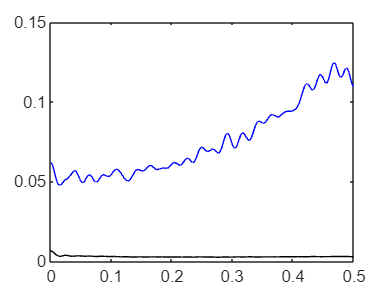

figure
xx=linspace(0,0.5,length(Gain));
plot(xx,mean(Gain_r1(ii,:)),'k')
hold on
plot(xx,mean(Gain_r3),'b')

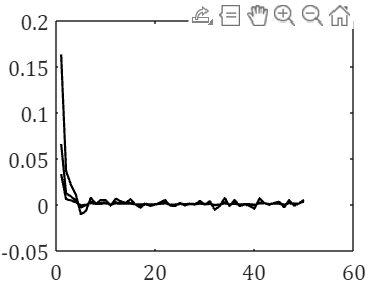

figure
xx=linspace(0,0.5,length(Gain));
%subplot(2,1,2)
plot(mean(K_r1(ii(33:64),:)),'k','linewidth',1.2)
hold on
plot(mean(K_r2(ii(33:64),:)),'k','linewidth',1.2)
plot(mean(K_r3(ii(33:64),:)),'k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
%xlim([-0.02 0.5])
%ylim([0.0017 0.012])
%yticks([0.005 0.01])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

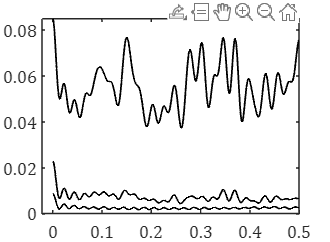

figure
xx=linspace(0,0.5,length(Gain));
%subplot(2,1,2)
plot(xx,mean(Gain_r(ii(33:64),:)),'k','linewidth',1.2)
hold on
plot(xx,mean(Gain_r2(ii(33:64),:)),'k','linewidth',1.2)
plot(xx,mean(Gain_r3(ii(33:64),:)),'k','linewidth',1.2)
%plot(xx,mean(Gain_r(ii,:)),'k','linewidth',1.2)
%hold on
%plot(xx,mean(Gain_r2(ii,:)),'k','linewidth',1.2)
%plot(xx,mean(Gain_r3(ii,:)),'k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
ylim([0 0.0849])
xticks([0 0.1 0.2 0.3 0.4 0.5])
%ylim([0.0017 0.012])
%yticks([0.005 0.01])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

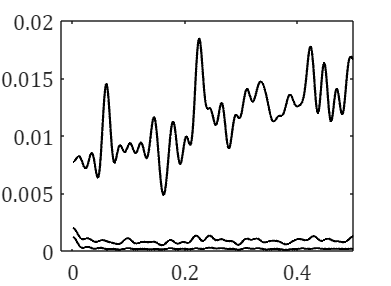

figure
xx=linspace(0,0.5,length(Gain));
%subplot(2,1,2)
plot(xx,mean(Gain_r1(ii(1:32),:)),'k','linewidth',1.2)
hold on
plot(xx,mean(Gain_r2(ii(1:32),:)),'k','linewidth',1.2)
plot(xx,mean(Gain_r3(ii(1:32),:)),'k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
%ylim([0.0017 0.012])
%yticks([0.005 0.01])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

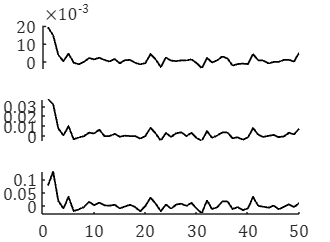

figure
xx=linspace(0,0.5,length(Gain));
subplot(3,1,1)
ik=45;
plot(K_r1(ik,:),'k','linewidth',1.2)
%plot(K_r(:,ik),'k','linewidth',1.2)
hold on
%plot(mean(K_r2(ii,:)),'k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([0 50])
%ylim([0.0017 0.012])
%yticks([0.005 0.01])
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(3,1,2)
plot(K_r2(ik,:),'k','linewidth',1.2)
hold on
%plot(mean(K_r2(ii,:)),'k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([0 50])
%ylim([0.0017 0.012])
%yticks([0.005 0.01])
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(3,1,3)
plot(K_r3(ik,:),'k','linewidth',1.2)
xlim([0 50])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

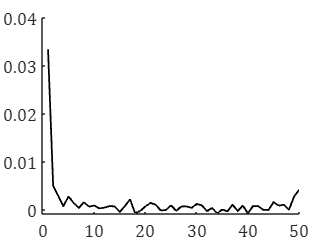

figure
plot(K_r(:,ik),'k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([0 50])
set (gcf,'Position',[500,100,300,220])

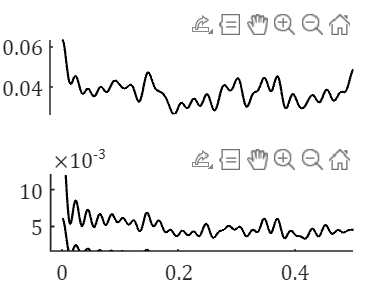

figure
xx=linspace(0,0.5,length(Gain));
subplot(2,1,2)
plot(xx,mean(Gain_r1(ii,:)),'k','linewidth',1.2)
hold on
plot(xx,mean(Gain_r2(ii,:)),'k','linewidth',1.2)
plot(xx,mean(Gain_r3(ii,:)),'k','linewidth',1.2)
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
ylim([0.0017 0.012])
yticks([0.005 0.01])

subplot(2,1,1)
%plot(xx,mean(Gain_r2),'--b')
plot(xx,mean(Gain_r3(ii,:)),'k','linewidth',1.2)
hold on
%plot(xx,mean(Gain_r2),'k')
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
set (gcf,'Position',[500,100,300,220])

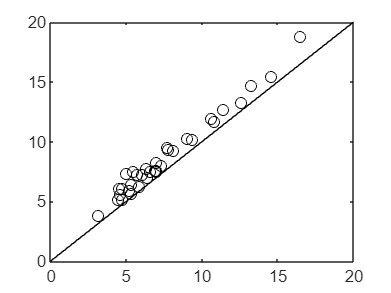

figure
iir=1:1:37;
plot(QTV_est_r2(iir+37),QTV_real2(iir+37),'ok')
hold on
xlim([0 20])
ylim([0 20])
xx=0:1:20;
plot(xx,xx,"k")

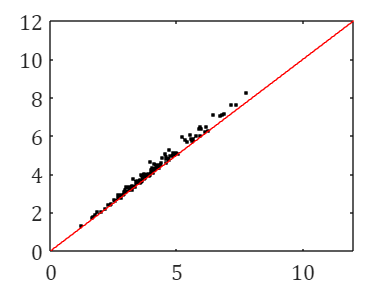

ss=1:1:37;
ss([3,12,26,32,35])=[];
ii(1:32)=ss;
ii(32+1:2*32)=ss+50;
ii(2*32+1:3*32)=ss+100;
ii(3*32+1:4*32)=ss+150;
figure
plot(QTV_est_r1(ii),QTV_real1(ii),'.k')
hold on
xx=0:1:12;
plot(xx,xx,'r')
xlim([0 12])
ylim([0 12])
%plot(QTV_est_r3(ss),QTV_real3(ss),'.k')
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)
set (gcf,'Position',[500,100,300,220])

ss=1:1:37;
ss([3,12,26,32,35])=[];
figure
xx=linspace(0,0.5,length(PSD_r(1,:)));
plot(xx,mean(PSD_r(ss,:)),'k')
hold on
plot(xx,mean(PSD_r(ss+50,:)),'r')
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
xlim([-0.02 0.5])
ylim([-3000 70000])
set (gcf,'Position',[500,100,300,220])